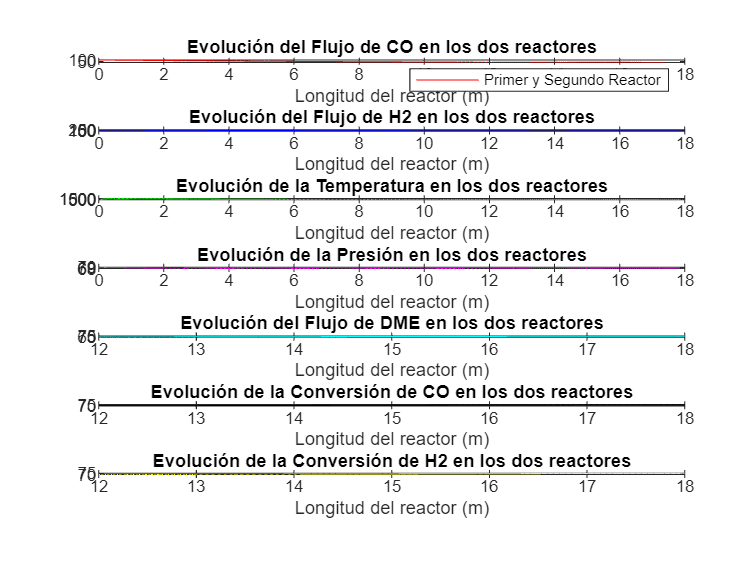

% Modelo de un reactor dual para la producción de DME

%% Definición de parámetros iniciales
F_CO = 100;       % Flujo inicial de CO (kmol/h)
F_H2 = 200;       % Flujo inicial de H2 (kmol/h)
T0 = 500;         % Temperatura inicial (K)
P0 = 70;          % Presión inicial (bar)
k1 = 0.1;         % Constante de reacción en el primer reactor
k2 = 0.05;        % Constante de reacción en el segundo reactor
U1 = 5;           % Coeficiente de transferencia de calor en el primer reactor
U2 = 3;           % Coeficiente de transferencia de calor en el segundo reactor
T_coolant1 = 450; % Temperatura del refrigerante del primer reactor (K)
T_coolant2 = 470; % Temperatura del refrigerante del segundo reactor (K)

%% Rango de longitudes a evaluar
% (basado en el artículo, se sugiere evaluar L1 entre 8 y 12 m, 
% y L2 entre 5 y 9 m, pero con la restricción de que L1 + L2 <= 18 m)
L1_vals = linspace(8, 12, 5); 
L2_vals = linspace(5, 9, 5);

%% Variables para almacenar los resultados
best_conversion = 0;
best_L1 = 0;
best_L2 = 0;

%% Bucle de búsqueda de las mejores longitudes de los dos reactores
for L1 = L1_vals
    for L2 = L2_vals
        
        % Restricción de longitud total
        if (L1 + L2) > 18
            continue;
        end
        
        %% Primer reactor (enfriado por agua)
        % Definimos el sistema de ecuaciones diferenciales
        dydz1 = @(z, y) [
            -k1*y(1);                                    % Consumo de CO
            -2*k1*y(1);                                  % Consumo de H2 (este factor puede ajustarse según la estequiometría)
            0.3*y(1)*y(2) - U1*(y(3) - T_coolant1)        % Balance de energía
        ];
        
        % Condiciones iniciales del primer reactor
        y0_1 = [F_CO; F_H2; T0];
        
        % Resolución numérica (desde z=0 hasta z=L1)
        [z1, y1] = ode45(dydz1, linspace(0, L1, 100), y0_1);
        
        %% Condiciones de entrada al segundo reactor
        F_CO2 = y1(end, 1);
        F_H2_2 = y1(end, 2);
        T1_out = y1(end, 3);
        
        %% Segundo reactor (enfriado por gas)
        % Definimos el sistema de ecuaciones diferenciales
        dydz2 = @(z, y) [
            -k2*y(1);                                    % Consumo de CO
            -1.5*k2*y(1);                                % Consumo de H2 (ajustable a la estequiometría real)
            0.2*y(1)*y(2) - U2*(y(3) - T_coolant2)        % Balance de energía
        ];
        
        % Condiciones iniciales del segundo reactor
        y0_2 = [F_CO2; F_H2_2; T1_out];
        
        % Resolución numérica (desde z=L1 hasta z=L1+L2)
        [z2, y2] = ode45(dydz2, linspace(L1, L1 + L2, 100), y0_2);
        
        %% Cálculo de la conversión de CO y H2
        X_CO = (F_CO - y2(:, 1)) / F_CO * 100; 
        X_H2 = (F_H2 - y2(:, 2)) / F_H2 * 100;
        
        % Actualización de la mejor configuración según la conversión de CO
        if max(X_CO) > best_conversion
            best_conversion = max(X_CO);
            best_L1 = L1;
            best_L2 = L2;
        end
        
    end
end

%% Cálculo de la caída de presión (con la restricción de 2 bar)
z_total = [z1; z2];
P = P0 * exp(-0.01 * z_total);
% Si la presión cae más de 2 bar (desde 70 bar hasta 68 bar), se limita:
P(P < (P0 - 2)) = (P0 - 2);

%% Cálculo de la concentración de DME (suponiendo eficiencia de 95%)
F_DME = (F_CO - y2(:, 1)) * 0.95;

%% Combinar los resultados de ambos reactores para graficar
y_total = [y1; y2];

%% Gráficas de resultados
figure;

% Evolución del Flujo de CO
subplot(7,1,1);
plot(z_total, y_total(:,1), '-r');
xlabel('Longitud del reactor (m)');
ylabel('Flujo de CO');
legend('Primer y Segundo Reactor');
title('Evolución del Flujo de CO en los dos reactores');

% Evolución del Flujo de H2
subplot(7,1,2);
plot(z_total, y_total(:,2), '-b');
xlabel('Longitud del reactor (m)');
ylabel('Flujo de H2');
title('Evolución del Flujo de H2 en los dos reactores');

% Evolución de la Temperatura
subplot(7,1,3);
plot(z_total, y_total(:,3), '-g');
xlabel('Longitud del reactor (m)');
ylabel('Temperatura (K)');
title('Evolución de la Temperatura en los dos reactores');

% Evolución de la Presión
subplot(7,1,4);
plot(z_total, P, '-m');
xlabel('Longitud del reactor (m)');
ylabel('Presión (bar)');
title('Evolución de la Presión en los dos reactores');

% Evolución del Flujo de DME
subplot(7,1,5);
plot(z2, F_DME, '-c');
xlabel('Longitud del reactor (m)');
ylabel('Flujo de DME');
title('Evolución del Flujo de DME en los dos reactores');

% Evolución de la Conversión de CO
X_CO = (F_CO - y2(:,1)) / F_CO * 100;  % Se recalcula para graficarlo con z2
subplot(7,1,6);
plot(z2, X_CO, '-k');
xlabel('Longitud del reactor (m)');
ylabel('Conversión de CO (%)');
title('Evolución de la Conversión de CO en los dos reactores');

% Evolución de la Conversión de H2
X_H2 = (F_H2 - y2(:,2)) / F_H2 * 100;
subplot(7,1,7);
plot(z2, X_H2, '-y');
xlabel('Longitud del reactor (m)');
ylabel('Conversión de H2 (%)');
title('Evolución de la Conversión de H2 en los dos reactores');


%% Mostrar la mejor configuración encontrada
fprintf('Mejor longitud para el primer reactor: %.2f m\n', best_L1);

Mejor longitud para el primer reactor: 12.00 m


fprintf('Mejor longitud para el segundo reactor: %.2f m\n', best_L2);

Mejor longitud para el segundo reactor: 6.00 m
